# Journey

An interactive script that can create a graphical representation of my journey so far.

First, lets establish the time line.

t1 = datetime(1989,6,7,8,0,0);
t2 = datetime('now');
lifetime = t1:t2;
alive = ones(length(lifetime), 1);

Now lets represent the major timespans of my journey

% obj = lifePeriod(periodName, totalTime, startTime, stopTime)
alive = lifePeriod('alive', lifetime, datetime(1989,6,7), datetime(2022, 12, 22));
schoolTime = lifePeriod('schoolTime', lifetime, datetime(1994,9,9), datetime(2005,7,20));
bracknellCollege = lifePeriod('bracknellCollege', lifetime, datetime(2005,9,9), datetime(2006, 7, 20));
partTimeJobs = lifePeriod('partTimeJobs', lifetime, datetime(2005, 1, 1), datetime(2008, 7, 20));
morePartTimeJobs = lifePeriod('morePartTimeJobs', lifetime, datetime(2011, 11, 1), datetime(2012, 4, 20));
academyOfContemporaryMusic = lifePeriod('academyOfContemporaryMusic', lifetime, datetime(2006,9,9), datetime(2008, 7,20));
undergrad = lifePeriod('undergrad', lifetime, datetime(2011,9,9), datetime(2015, 7,20));
masters = lifePeriod('masters', lifetime, datetime(2015,9,9), datetime(2017, 7, 20));
PhD = lifePeriod('PhD', lifetime, datetime(2019,1,2), datetime(2022, 12, 22));
soundEngineering = lifePeriod('soundEngineering', lifetime, datetime(2009,1,1), datetime(2015, 4, 15));
barWork = lifePeriod('barWork', lifetime, datetime(2008,1,1) , datetime(2011, 9, 9));
aminaTechnologies = lifePeriod('aminaTechnologies', lifetime, datetime(2015,4,1), datetime(2017, 1, 29));
bowersAndWilkins = lifePeriod('bowersAndWilkins', lifetime, datetime(2017,1,30), datetime(2019, 1, 1));
climbing = lifePeriod('climbing', lifetime, datetime(2011,9,9), datetime('now'));
modularSynthesis = lifePeriod('modularSynthesis', lifetime, datetime(2018, 1, 1), datetime('now'));
periods = [alive, schoolTime, bracknellCollege, partTimeJobs, morePartTimeJobs,...
    academyOfContemporaryMusic, undergrad, masters, PhD, soundEngineering, barWork,...
    aminaTechnologies, bowersAndWilkins, climbing, modularSynthesis];

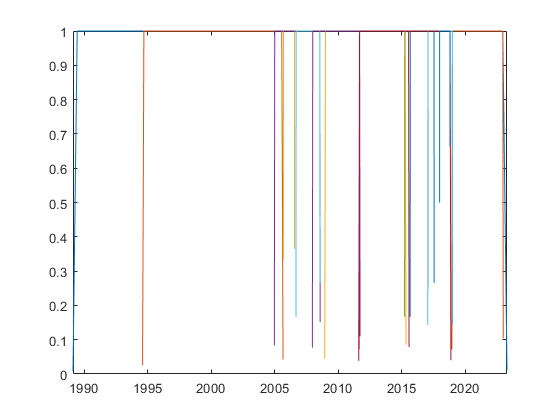

plot(periods(1).periodTime, periods(1).inProgress);
hold on;
for index = 2 : length(periods)
    plot(periods(index).periodTime, periods(index).inProgress);
end

% Load data
load data xfit yfit xdata_m ydata_m ydata_s xVdata yVdata xmodel ymodel ...
    ymodelL ymodelU c cint

% Create basic plot
figure
hold on
hFit = line(xfit  , yfit);
hE = errorbar(xdata_m, ydata_m, ydata_s);
hData = line(xVdata, yVdata);
hModel = line(xmodel, ymodel);
hCI(1) = line(xmodel, ymodelL);
hCI(2) = line(xmodel, ymodelU);

% Adjust line properties (functional)
set(hFit, 'Color', [0 0 .5])
set(hE, 'LineStyle', 'none', 'Marker', '.', 'Color', [.3 .3 .3])
set(hData, 'LineStyle', 'none', 'Marker', '.')
set(hModel, 'LineStyle', '--', 'Color', 'r')
set(hCI(1), 'LineStyle', '-.', 'Color', [0 .5 0])
set(hCI(2), 'LineStyle', '-.', 'Color', [0 .5 0])

% Adjust line properties (aesthetics)
set(hFit, 'LineWidth', 2)
set(hE, 'LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6, ...
    'MarkerEdgeColor', [.2 .2 .2], 'MarkerFaceColor' , [.7 .7 .7])
set(hData, 'Marker', 'o', 'MarkerSize', 5, ...
    'MarkerEdgeColor', 'none', 'MarkerFaceColor', [.75 .75 1])
set(hModel, 'LineWidth', 1.5)
set(hCI(1), 'LineWidth', 1.5)
set(hCI(2), 'LineWidth', 1.5)

% Add labels
hTitle = title('My Publication-Quality Graphics');
hXLabel = xlabel('Length (m)');
hYLabel = ylabel('Mass (kg)');

% Add text
hText = text(10, 800, ...
    sprintf('{\\itC = %0.1g \\pm %0.1g (CI)}', c, cint(2)-c));

% Add legend
hLegend = legend([hE, hFit, hData, hModel, hCI(1)], ...
    'Data ({\it\mu} \pm {\it\sigma})', 'Fit (C{\itx}^3)', ...
    'Validation Data', 'Model (C{\itx}^3)', '95% CI', ...
    'Location', 'NorthWest');

% Adjust font
set(gca, 'FontName', 'Helvetica')
set([hTitle, hXLabel, hYLabel, hText], 'FontName', 'AvantGarde')
set([hLegend, gca], 'FontSize', 8)
set([hXLabel, hYLabel, hText], 'FontSize', 10)
set(hTitle, 'FontSize', 12, 'FontWeight' , 'bold')

% Adjust axes properties
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'YGrid', 'on', ...
    'XColor', [.3 .3 .3], 'YColor', [.3 .3 .3], 'YTick', 0:500:2500, ...
    'LineWidth', 1)

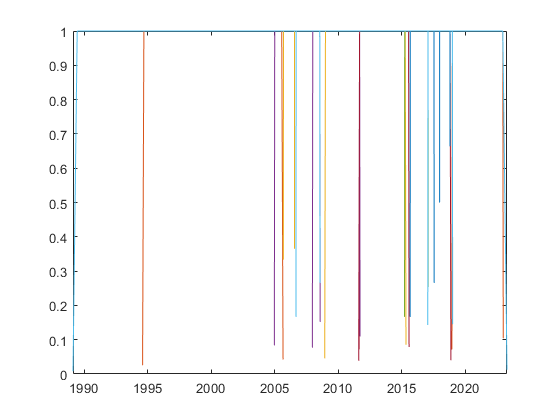

hold off;
hold on;
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);
plot(alive.periodTime, alive.inProgress);

hold off;

and in vectors

schoolTimeDT = datetime(1994,9,9) : datetime(2005,7,20);
bracknellCollegeDT = datetime(2005,9,9) : datetime(2006, 7, 20);
partTimeJobsDT = datetime(2005, 1, 1) : datetime(2008, 7, 20);
morePartTimeJobsDT = datetime(2011, 11, 1) : datetime(2012, 4, 20);
academyOfContemporaryMusicDT = datetime(2006,9,9) : datetime(2008, 7,20);
undergradDT = datetime(2011,9,9) : datetime(2015, 7,20);
mastersDT = datetime(2015,9,9) : datetime(2017, 7, 20);
PhDDT = datetime(2019,1,2) : datetime(2022, 12, 22);
soundEngineeringDT = datetime(2009,1,1) : datetime(2015, 4, 15);
barWorkDT = datetime(2008,1,1) : datetime(2011, 9, 9);
aminaTechnologiesDT = datetime(2015,4,1) : datetime(2017, 1, 29);
bowersAndWilkinsDT = datetime(2017,1,30) : datetime(2019, 1, 1);
climbingDT = datetime(2011,9,9) : datetime('now');
modularSynthesisDT = datetime(2018, 1, 1) : datetime('now');

Lets create a boolean array of an event being true

schoolTimeInProgress = ones(length(schoolTimeDT), 1);
bracknellCollegeInProgress = ones(length(bracknellCollegeDT), 1);
partTimeJobsInProgress = ones(length(partTimeJobsDT), 1);
morePartTimeJobsInProgress = ones(length(morePartTimeJobsDT), 1);
academyOfContemporaryMusicInProgress = ones(length(academyOfContemporaryMusicDT), 1);
undergradInProgress = ones(length(undergradDT), 1);
mastersInProgress = ones(length(mastersDT), 1);
PhDInProgress = ones(length(PhDDT), 1);
soundEngineeringInProgress = ones(length(soundEngineeringDT), 1);
barWorkInProgress = ones(length(barWorkDT), 1);
aminaTechnologiesInProgress = ones(length(aminaTechnologiesDT), 1);
bowersAndWilkinsInProgress = ones(length(bowersAndWilkinsDT), 1);
climbingInProgress = ones(length(climbingDT), 1);
modularSynthesisInProgress = ones(length(modularSynthesisDT), 1);

Lets do a nice overlapping plot

plot(lifetime, alive)

Error using plot
Data must be numeric, datetime, duration or an array convertible to double.

hold on
plot(schoolTimeDT, schoolTimeInProgress);
plot(bracknellCollegeDT, bracknellCollegeInProgress);
plot(partTimeJobsDT, partTimeJobsInProgress);
plot(morePartTimeJobsDT, morePartTimeJobsInProgress);
plot(academyOfContemporaryMusicDT, academyOfContemporaryMusicInProgress);
plot(undergradDT, undergradInProgress);
plot(mastersDT, mastersInProgress);
plot(PhDDT, PhDInProgress);
plot(soundEngineeringDT, soundEngineeringInProgress);
plot(barWorkDT, barWorkInProgress);
plot(aminaTechnologiesDT, aminaTechnologiesInProgress);
plot(bowersAndWilkinsDT, bowersAndWilkinsInProgress);
plot(climbingDT, climbingInProgress);
plot(modularSynthesisDT, modularSynthesisInProgress);
hold off